close all;
clear;
clc;

% 注意：两个椭圆所在画幅的实际宽度和高度要分别相等
img1 = imread('src/11.png');
img2 = imread('src/22.png');

% 输入图窗实际大小：
figWidth = 5;
figHeight = 5;
figArea = figWidth*figHeight;

% 灰度
img1Gray = rgb2gray(img1);
img2Gray = rgb2gray(img2);

% 统一画幅
[w1,h1] = isize(img1Gray);
[w2,h2] = isize(img2Gray);
w = min(w1,w2);
h = min(h1,h2);
img1Gray = imresize(img1Gray,[w,h]);
img2Gray = imresize(img2Gray,[w,h]);

subplot(2,3,1);
imshow(img1Gray);
hold on;
title('gray image of 1st');
subplot(2,3,4);
imshow(img2Gray);
hold on;
title('gray image of 2nd');

% 二值化，分别求面积
img1Bin = imbinarize(img1Gray,0.9);
img1BW = ~img1Bin;
area1 = bwArea(img1BW,figArea);
fprintf('the area of the first ellipse is %.4f\n',area1);

the area of the first ellipse is 1.8604


img2Bin = imbinarize(img2Gray,0.9);
img2BW = ~img2Bin;
area2 = bwArea(img2BW,figArea);
fprintf('the area of the second ellipse is %.4f\n',area2);

the area of the second ellipse is 1.6089


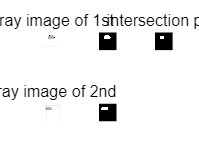

subplot(2,3,2);
imshow(img1BW);
subplot(2,3,5);
imshow(img2BW);

% 求交集
imgInter = img1BW & img2BW;
subplot(2,3,3);
imshow(imgInter);
hold on;
title('intersection part');

areaInter = bwArea(imgInter,figArea);
fprintf('the area of the intersection part is %.4f\n',areaInter);

the area of the intersection part is 0.9469


% fprintf('LJJ I love you mo~~\n');

LJJ I love you mo~~


## 求二值图区域面积的函数

function area = bwArea(imgBW,figArea)
% 求交集的像素面积
[imgWidth,imgHeight] = isize(imgBW);
stats = regionprops(imgBW,'Area');
areaPix = stats.Area; % 得到像素面积
areaPor = areaPix/(imgWidth*imgHeight);

% 最终面积
area = figArea*areaPor;
end